clear
clc
T= 273.15 + [ 58 , 68 , 83, 90];
M_a = 60.052

M_a = 60.0520

M_b = 74.121;
G= -8.889e3;
R = 8.314;
To = 298.15;
H = -3.887e3;
Ko = exp(-G/(R*(To)))

Ko = 36.0888

K = Ko.*(exp((H./R).*((1/To)-(1./(T)))))

K =    30.8679   29.6166   27.9555   27.2570




V_a= 100; % ml
V_b = 150;  % ml
V= V_a + V_b;   % ml

rho_a= 1.05;    % g/ml
rho_b = 0.81;  % g/ml 

No_a = (rho_a*V_a)/M_a

No_a = 1.7485


No_b = (rho_b*V_b)/M_b

No_b = 1.6392

Co_a = No_a*1000/V

Co_a = 6.9939

Co_b = No_b*1000/V

Co_b = 6.5568

C_NaOH = 0.5  ; % mol/l
t = [0,10,20,40,50,60,70];

titre_val = [28 26.3 24.5 23.3 22.7 21.8 21;
    27.4 26.3 22.6 19.3 18.8 18.5 18.5;
    25.7 19.7 18.8 16.8 14.7 14.6 13.6;
    23.9 18.4 17.1 14.8 13.7 12.7 12];
v_sample = 2;

Nf_a = zeros(4,7);
for i = 1:4
    for j = 1:7
        Nf_a(i,j) = titre_val(i,j)*C_NaOH*(250/v_sample)/1000;
    end
end
Nf_a

Nf_a =     1.7500    1.6438    1.5312    1.4563    1.4187    1.3625    1.3125
    1.7125    1.6438    1.4125    1.2063    1.1750    1.1562    1.1562
    1.6062    1.2312    1.1750    1.0500    0.9187    0.9125    0.8500
    1.4937    1.1500    1.0688    0.9250    0.8562    0.7937    0.7500


X = zeros(4,7);
for i = 1:4
    for j = 1:7
        X(i,j) = (No_a - Nf_a(i,j))/No_a;
    end
end
X(1,1) = 0;
X

X =          0    0.0599    0.1242    0.1671    0.1886    0.2208    0.2494
    0.0206    0.0599    0.1922    0.3101    0.3280    0.3387    0.3387
    0.0813    0.2958    0.3280    0.3995    0.4745    0.4781    0.5139
    0.1457    0.3423    0.3888    0.4710    0.5103    0.5460    0.5711


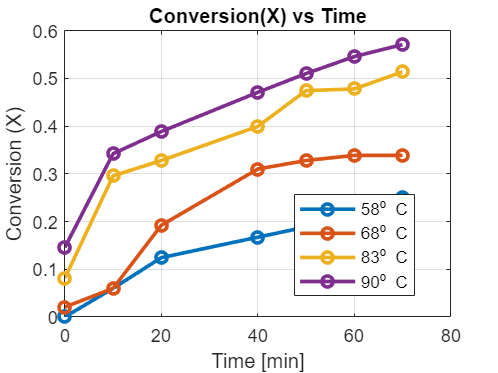


% Plotting conversion vs t
plot(t,X(1,:),"-o",LineWidth=2)
hold on
plot(t,X(2,:),"-o",LineWidth=2)
plot(t,X(3,:),"-o",LineWidth=2)
plot(t,X(4,:),"-o",LineWidth=2)
grid on;
ylabel("Conversion (X)")
xlabel("Time [min]")
title("Conversion(X) vs Time")
legend(["58^o C","68^o C","83^o C","90^o C"],Location="best")
hold off

Differential Analysis

dX = zeros(4,7);
for i = 1:4
    for j = 2:7
        dX(i,j) = (X(i,j)-X(i,j-1))/(t(j)-t(j-1));
    end
end
dX 

dX =          0    0.0060    0.0064    0.0021    0.0021    0.0032    0.0029
         0    0.0039    0.0132    0.0059    0.0018    0.0011         0
         0    0.0214    0.0032    0.0036    0.0075    0.0004    0.0036
         0    0.0197    0.0046    0.0041    0.0039    0.0036    0.0025


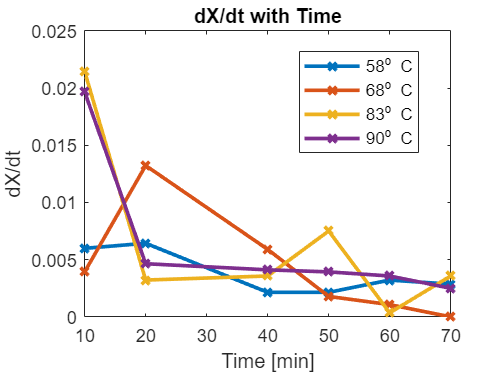


for i = 1:4
    plot(t(2:end),dX(i,2:end),"-x ",LineWidth=2)
    hold on
end
title("dX/dt with Time")
xlabel("Time [min]")
ylabel("dX/dt")
legend(["58^o C","68^o C","83^o C","90^o C"],Location="best")
hold off


f2 = zeros(4,7);
for i = 1:4
    for j = 2:7
        f2(i,j) = Co_a*((1-X(i,j))*((Co_b/Co_a)-X(i,j))) - (X(i,j)*X(i,j))/K(i);
    end
end
f2 

f2 =          0    5.7701    4.9807    4.4865    4.2490    3.9047    3.6108
         0    5.7701    4.2100    3.0239    2.8611    2.7655    2.7655
         0    3.1572    2.8609    2.2540    1.6933    1.6686    1.4309
         0    2.7337    2.3404    1.7180    1.4537    1.2320    1.0874


k1 = zeros(4,1);

i=1;
    fit = fitlm(f2(i,2:end),dX(i,2:end));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.5710

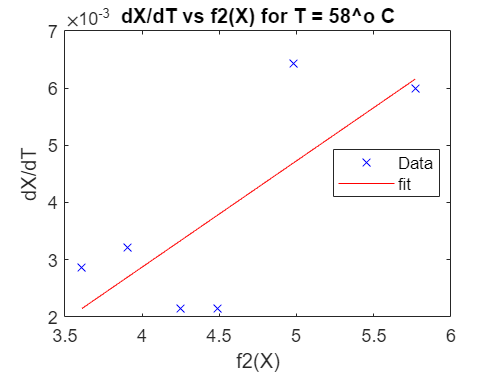

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("dX/dT vs f2(X) for T = " + (T(i)-273.15) + "^o C")
    ylabel("dX/dT")
    xlabel("f2(X)")

    k1(i) = fit.Coefficients.Estimate(2);
i=2;
    fit = fitlm(f2(i,2:end),dX(i,2:end));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.1631

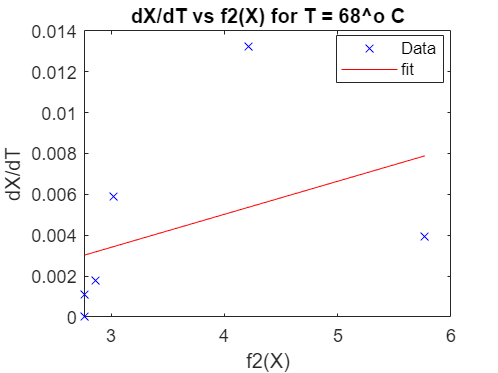

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("dX/dT vs f2(X) for T = " + (T(i)-273.15) + "^o C")
    ylabel("dX/dT")
    xlabel("f2(X)")

    k1(i) = fit.Coefficients.Estimate(2);
i=3;
    fit = fitlm(f2(i,2:end),dX(i,2:end));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.4013

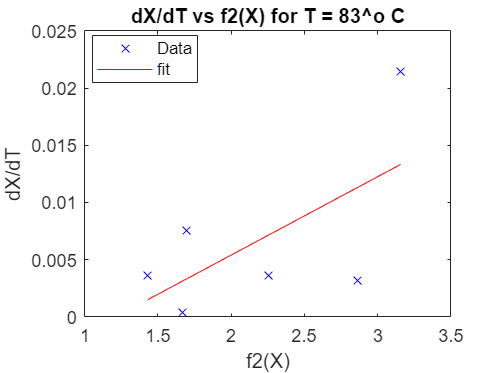

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("dX/dT vs f2(X) for T = " + (T(i)-273.15) + "^o C")
    ylabel("dX/dT")
    xlabel("f2(X)")

    k1(i) = fit.Coefficients.Estimate(2);
i=4;
    fit = fitlm(f2(i,2:end),dX(i,2:end));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.6307

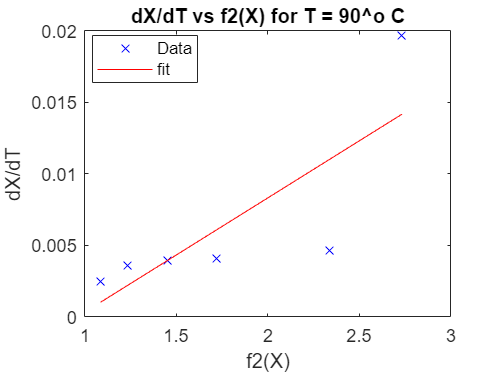

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("dX/dT vs f2(X) for T = " + (T(i)-273.15) + "^o C")
    ylabel("dX/dT")
    xlabel("f2(X)")

    k1(i) = fit.Coefficients.Estimate(2);
k1

k1 =     0.0019
    0.0016
    0.0068
    0.0080


k2 = k1./K'

k2 = 1.0e-03 *

    0.0602
    0.0546
    0.2449
    0.2929



%finding ln k1 vs 1/T
fit = fitlm(1./T,log(k1));
 p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.8547

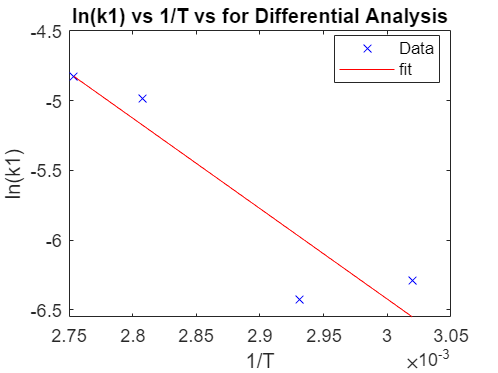

    title("ln(k1) vs 1/T vs for Differential Analysis")
    ylabel("ln(k1)")
    xlabel("1/T")

intercept = fit.Coefficients.Estimate(1)

intercept = 13.0122

slope = fit.Coefficients.Estimate(2)

slope = -6.4782e+03


% K0 and Ea values
% for forward reaction,
% ln(k0) = intercept
k0 = exp(intercept)

k0 = 4.4783e+05

% -E/RT = slope
Ea = -8.314*slope

Ea = 5.3859e+04

fprintf("For Forward reaction, k0 = %d",k0)

For Forward reaction, k0 = 4.478329e+05

fprintf("And the Activation Energy is %d J/mole",Ea)

And the Activation Energy is 5.385943e+04 J/mole


%finding ln k2 vs 1/T
fit = fitlm(1./T,log(k2));
 p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.8711

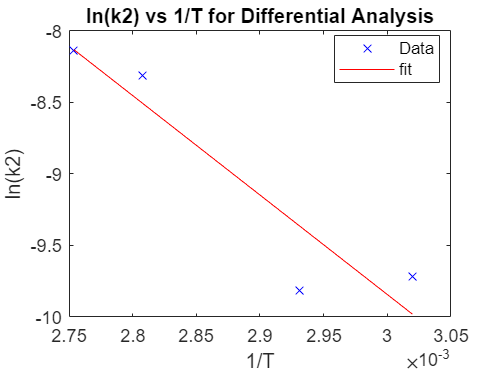

    title("ln(k2) vs 1/T for Differential Analysis")
    ylabel("ln(k2)")
    xlabel("1/T")

intercept = fit.Coefficients.Estimate(1)

intercept = 10.9943

slope = fit.Coefficients.Estimate(2)

slope = -6.9457e+03


% K0 and Ea values
% for backward reaction,
% ln(k0) = intercept
k0 = exp(intercept)

k0 = 5.9533e+04

% -E/RT = slope
Ea = -8.314*slope

Ea = 5.7746e+04

fprintf("For Backward reaction, k0 = %d",k0)

For Backward reaction, k0 = 5.953258e+04

fprintf("And the Activation Energy is %d J",Ea)

And the Activation Energy is 5.774643e+04 J

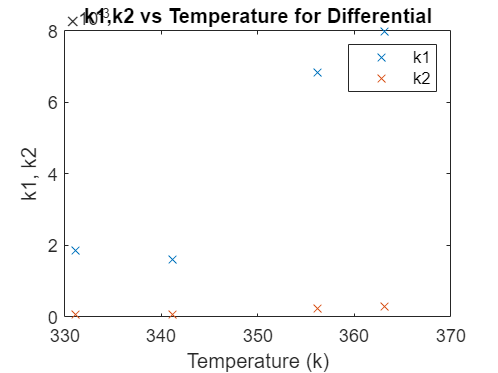


plot(T,k1,"x ")
hold on
title("k1,k2 vs Temperature for Differential")
plot(T,k2,"x ")
hold off
xlabel("Temperature (k)")
ylabel("k1, k2")
legend("k1","k2")

Integral Analysis

f1=zeros(4,7);
for i=1:4
    for j=1:7
    const = (K.*(K.*(Co_b^2 + Co_a^2 - 2*Co_b*Co_a) + 4*Co_b*Co_a)).^0.5;
    num = (2*Co_a*K(i) -2*Co_a)*X(i,j) - const(i) + (-Co_b-Co_a)*K(i);
    den = (2*Co_a*K(i) -2*Co_a)*X(i,j) + const(i) + (-Co_b-Co_a)*K(i);
    f1(i,j) = K(i)*log(abs(num/den))/const(i);
    end
end
f1

f1 =     0.1493    0.1590    0.1710    0.1801    0.1850    0.1929    0.2006
    0.1525    0.1591    0.1859    0.2191    0.2252    0.2291    0.2291
    0.1630    0.2146    0.2254    0.2538    0.2931    0.2953    0.3192
    0.1757    0.2306    0.2492    0.2910    0.3168    0.3448    0.3678



k1 = zeros(1,4);
i=1;
    fit = fitlm(t,f1(i,:));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.9816

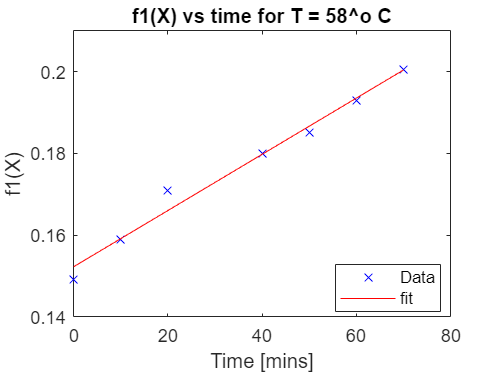

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("f1(X) vs time for T = " + (T(i)-273.15) + "^o C")
    ylabel("f1(X)")
    xlabel("Time [mins]")

    k1(i) = fit.Coefficients.Estimate(2);
i=2;
    fit = fitlm(t,f1(i,:));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.9195

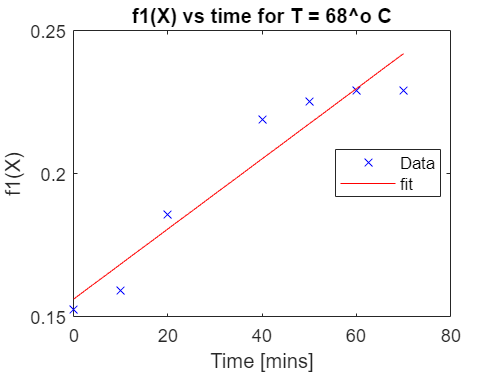

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("f1(X) vs time for T = " + (T(i)-273.15) + "^o C")
    ylabel("f1(X)")
    xlabel("Time [mins]")

    k1(i) = fit.Coefficients.Estimate(2);
i=3;
    fit = fitlm(t,f1(i,:));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.9584

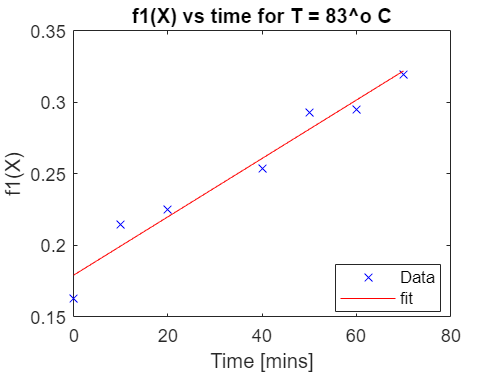

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("f1(X) vs time for T = " + (T(i)-273.15) + "^o C")
    ylabel("f1(X)")
    xlabel("Time [mins]")

    k1(i) = fit.Coefficients.Estimate(2);
i=4;
    fit = fitlm(t,f1(i,:));
    p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.9821

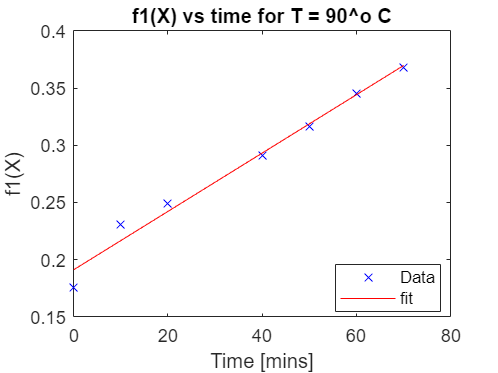

    %plot(f2(i,2:end),X(i,2:end),"x",LineWidth=2) 
    title("f1(X) vs time for T = " + (T(i)-273.15) + "^o C")
    ylabel("f1(X)")
    xlabel("Time [mins]")

    k1(i) = fit.Coefficients.Estimate(2);
k1

k1 =     0.0007    0.0012    0.0020    0.0026


k2 = k1./K

k2 = 1.0e-04 *

    0.2229    0.4139    0.7299    0.9356




%finding ln k1 vs 1/T
fit = fitlm(1./T,log(k1));
 p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.9873

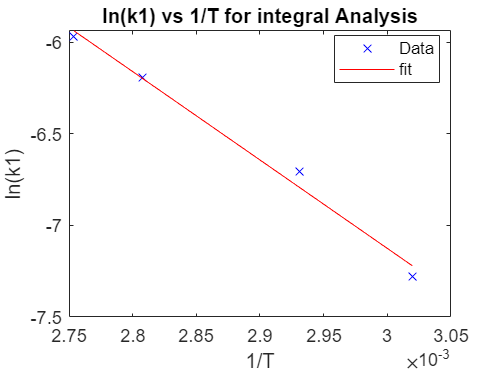

    title("ln(k1) vs 1/T for integral Analysis")
    ylabel("ln(k1)")
    xlabel("1/T")

intercept = fit.Coefficients.Estimate(1)

intercept = 7.3353

slope = fit.Coefficients.Estimate(2)

slope = -4.8203e+03


% K0 and Ea values
% for forward reaction,
% ln(k0) = intercept
k0 = exp(intercept)

k0 = 1.5335e+03

% -E/RT = slope
Ea = -8.314*slope

Ea = 4.0076e+04

fprintf("For Forward reaction, k0 = %d",k0)

For Forward reaction, k0 = 1.533510e+03

fprintf("And the Activation Energy is %d J/mole",Ea)

And the Activation Energy is 4.007558e+04 J/mole


%finding ln k2 vs 1/T
fit = fitlm(1./T,log(k2));
 p=plot(fit);
    p(end-1,1).Visible='off';
    p(end,1).Visible='off';
    legend("Data","fit")
    R2 = fit.Rsquared.Ordinary

R2 = 0.9894

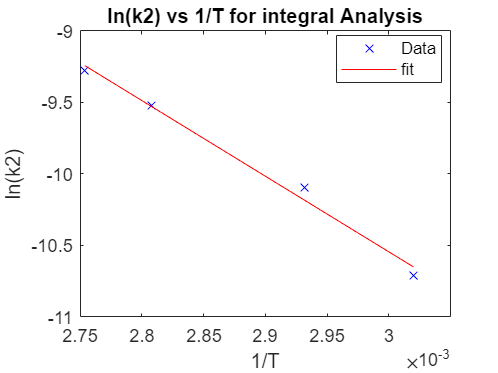

    title("ln(k2) vs 1/T for integral Analysis")
    ylabel("ln(k2)")
    xlabel("1/T")

intercept = fit.Coefficients.Estimate(1)

intercept = 5.3174

slope = fit.Coefficients.Estimate(2)

slope = -5.2878e+03



% K0 and Ea values
% for backward reaction,
% ln(k0) = intercept
k0 = exp(intercept)

k0 = 203.8569

% -E/RT = slope
Ea = -8.314*slope

Ea = 4.3963e+04

fprintf("For Backward reaction, k0 = %d",k0)

For Backward reaction, k0 = 2.038569e+02

fprintf("And the Activation Energy is %d J/mole",Ea)

And the Activation Energy is 4.396258e+04 J/mole

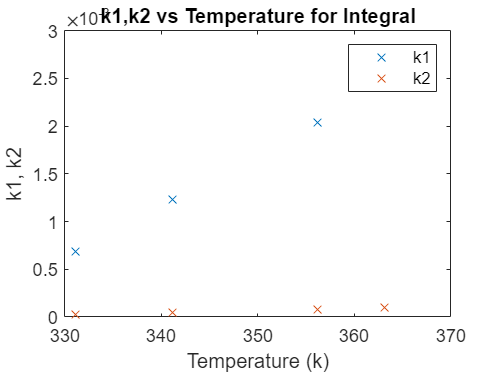

plot(T,k1,"x ")
hold on
title("k1,k2 vs Temperature for Integral")
plot(T,k2,"x ")
hold off
xlabel("Temperature (k)")
ylabel("k1, k2")
legend("k1","k2")